Calculates the normalized active force in muscle fibers with respect to the active force-velocity relationship (applies to all muscles in OpenSim musckuloskeletal model)

"velocity of muscle fiber" = "speed of contraction"

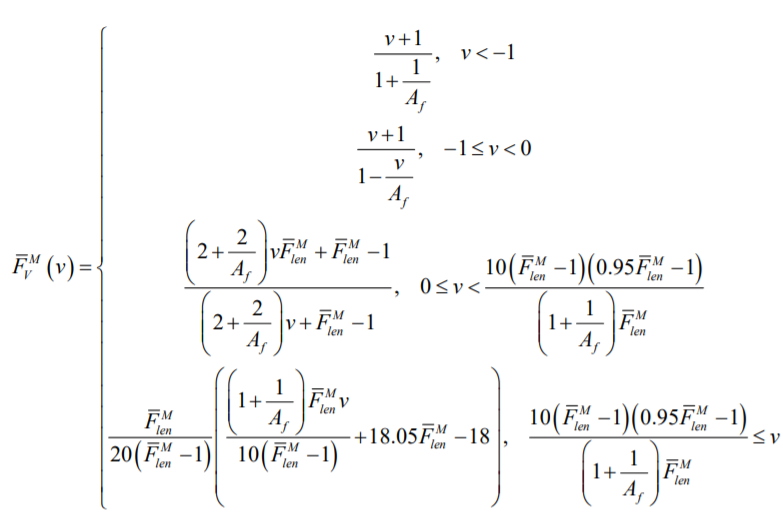

function FM = Thelen2003_Force_Velocity(fib_vel)
    Af = 0.3; % a shape factor for the force-velocity relationship
    FM_len = 1.8; % maximum normalzied muscle force achievable when the fiber is lengthening
    A = 1 + 1/Af;
    C = 10*(FM_len - 1)*(0.95*FM_len - 1) / (A * FM_len);
    FM = zeros(size(fib_vel));
    for i = 1:length(fib_vel)
        v = fib_vel(i);
        if v < -1
            FM(i) = (v+1) / A;
        elseif (-1 <= v && v < 0)
            FM(i) = (v+1) ./ (1 - v/Af);
        elseif (0 <= v && v < C)
            num = 2*A*v*FM_len + FM_len - 1;
            den = 2*A*v + FM_len - 1;
            FM(i) = num./den;
        elseif C <= v
            num = A*FM_len*v;
            den = 10*(FM_len - 1);
            FM(i) = (FM_len/(20*(FM_len - 1))) * (num/den + 18.05*FM_len - 18);
        end
    end
end